# Laboratorium 12

Karolina Piotrowska

## Wstęp

Transformacja Fouriera stosuje w jądrze funkcje sinusoidalne, natomiast transformacja falkowa stosuje funkcje (falki), które spełniają wymagania analizy częstotliwościowej. Funkcje okresowe (sin/cos) są dobre do określenia częstotliwości, ale nie w dziedzinie czasu. Transformacja falkowa sluzy do analizy sygnalow niestacjonarnych, gdyz dostarcza informacji o czasowo-czestotliwosciowych zmianach sygnalow

## Pytania

1) **W jaki sposób zastosować falki do ekstrakcji cech?** Po wykonaniu transformacji falkowej analizuje się współczynniki.

2) **Jakie parametry falek możemy zmieniać w toolboxie? **Rodzaj falki, poziom dekompozycji.

3) **Czym różnią się współczynniki a1, d1, d2, d3, d4, d5?** Współczynniki dj(k) zawierają informację o wysokich częstotliwościach oraz tworzą zbiór detali. Natomiast współczynniki aj(k) zawierają informację dolnoprzepustową, czyli stanowią aproksymację sygnału. 

4) **Czym różni się transformacja falkowa od filtrów?** Są w stanie doskonale zrekonstruować funkcje o kształtach wielomianów liniowych i wyższych rzędów takich jak prostokąt, wielomiany drugiego rzędu.

## Rozwiązanie zadań

### Zadanie 1

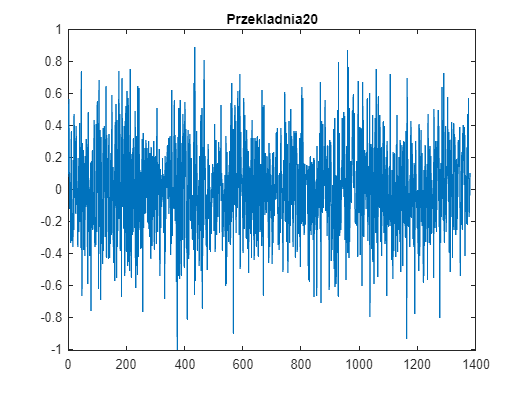

clear all;
load falki_ws.mat

falka = 'db2';
num = 5;

% P20
[c, l] = wavedec(P20, num, falka);
[d5_P20] = detcoef(c, l, num);
figure(1), plot(d5_P20), title('Przekladnia20');

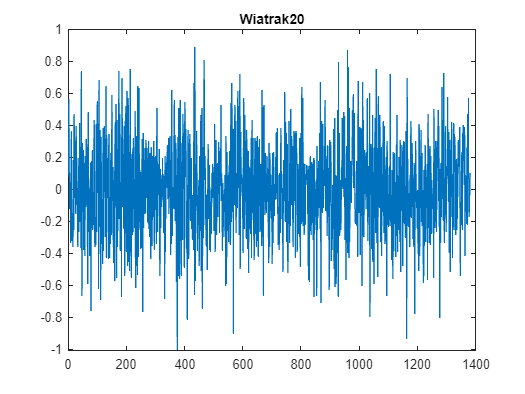

% P21
[c, l] = wavedec(P21, num, falka);
[d5_P21] = detcoef(c, l, num);
% P23
[c, l] = wavedec(P23, num, falka);
[d5_P23] = detcoef(c, l, num);
% P24
[c, l] = wavedec(P24, num, falka);
[d5_P24] = detcoef(c, l, num);
% W20
[c, l] = wavedec(P20, num, falka);
[d5_W20] = detcoef(c, l, num);
figure(5), plot(d5_W20), title('Wiatrak20');

% W21
[c, l] = wavedec(P21, num, falka);
[d5_W21] = detcoef(c, l, num);
% W23
[c, l] = wavedec(P23, num, falka);
[d5_W23] = detcoef(c, l, num);
% W24
[c, l] = wavedec(P24, num, falka);
[d5_W24] = detcoef(c, l, num);

### Zadanie 2

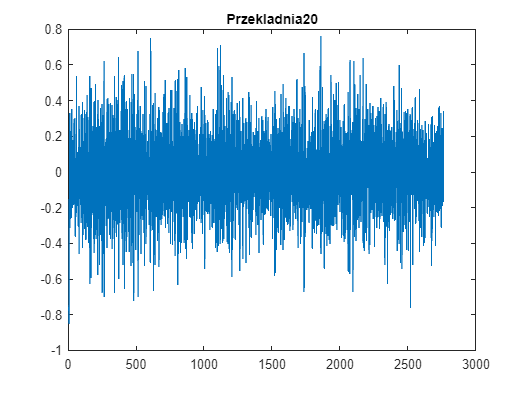

falka = 'coif2';
num = 4;

% P20
[c, l] = wavedec(P20, num, falka);
[d5_P20] = appcoef(c, l, falka, num);
figure(1), plot(d5_P20), title('Przekladnia20');

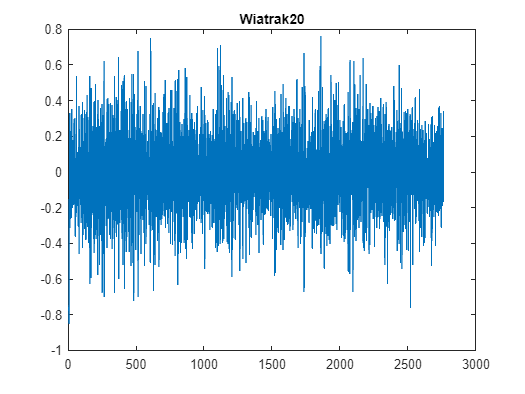

% P21
[c, l] = wavedec(P21, num, falka);
[d5_P21] = appcoef(c, l, falka, num);
% P23
[c, l] = wavedec(P23, num, falka);
[d5_P23] = appcoef(c, l, falka, num);
% P24
[c, l] = wavedec(P24, num, falka);
[d5_P24] = appcoef(c, l, falka, num);
% W20
[c, l] = wavedec(P20, num, falka);
[d5_W20] = appcoef(c, l, falka, num);
figure(5), plot(d5_W20), title('Wiatrak20');

% W21
[c, l] = wavedec(P21, num, falka);
[d5_W21] = appcoef(c, l, falka, num);
% W23
[c, l] = wavedec(P23, num, falka);
[d5_W23] = appcoef(c, l, falka, num);
% W24
[c, l] = wavedec(P24, num, falka);
[d5_W24] = appcoef(c, l, falka, num);

### Zadanie 3

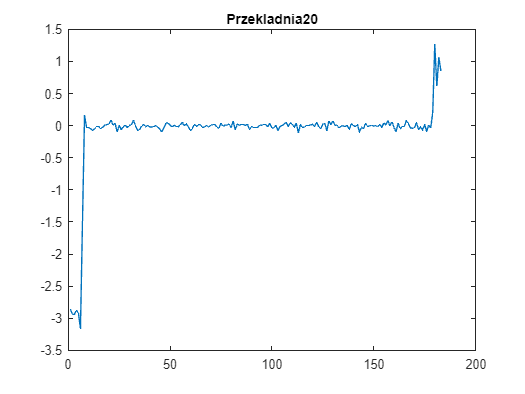

falka = 'coif2';
num = 8;

% P20
[c, l] = wavedec(P20, num, falka);
[d5_P20] = appcoef(c, l, falka, num);
figure(1), plot(d5_P20), title('Przekladnia20');

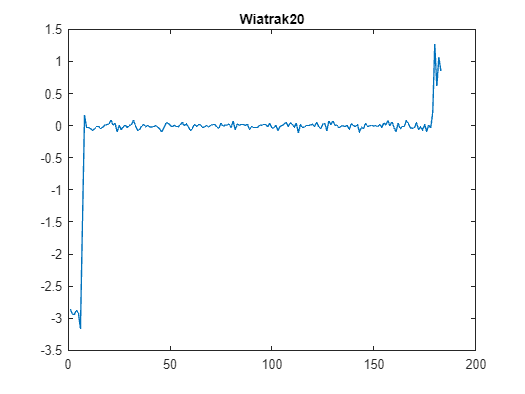

% P21
[c, l] = wavedec(P21, num, falka);
[d5_P21] = appcoef(c, l, falka, num);
% P23
[c, l] = wavedec(P23, num, falka);
[d5_P23] = appcoef(c, l, falka, num);
% P24
[c, l] = wavedec(P24, num, falka);
[d5_P24] = appcoef(c, l, falka, num);
% W20
[c, l] = wavedec(P20, num, falka);
[d5_W20] = appcoef(c, l, falka, num);
figure(5), plot(d5_W20), title('Wiatrak20');

% W21
[c, l] = wavedec(P21, num, falka);
[d5_W21] = appcoef(c, l, falka, num);
% W23
[c, l] = wavedec(P23, num, falka);
[d5_W23] = appcoef(c, l, falka, num);
% W24
[c, l] = wavedec(P24, num, falka);
[d5_W24] = appcoef(c, l, falka, num);

### Zadanie 4

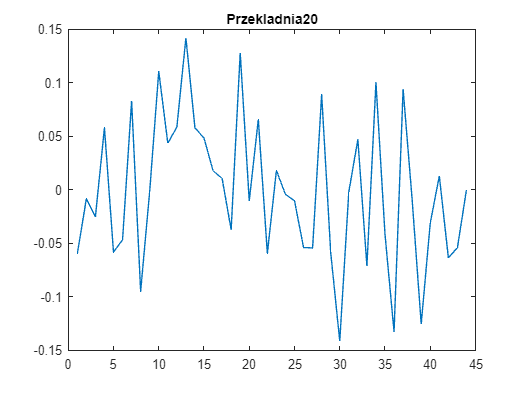

falka = 'haar';
num = 10;

% P20
[c, l] = wavedec(P20, num, falka);
[d5_P20] = detcoef(c, l, num);
figure(1), plot(d5_P20), title('Przekladnia20');

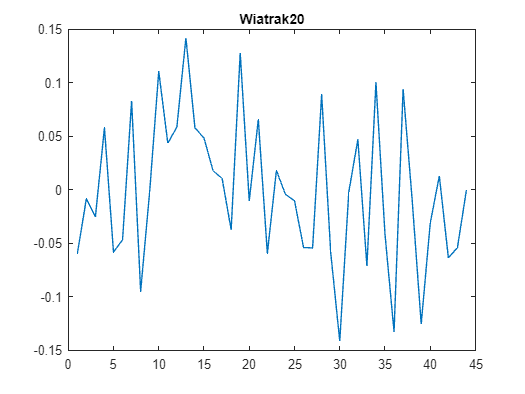

% P21
[c, l] = wavedec(P21, num, falka);
[d5_P21] = detcoef(c, l, num);
% P23
[c, l] = wavedec(P23, num, falka);
[d5_P23] = detcoef(c, l, num);
% P24
[c, l] = wavedec(P24, num, falka);
[d5_P24] = detcoef(c, l, num);
% W20
[c, l] = wavedec(P20, num, falka);
[d5_W20] = detcoef(c, l, num);
figure(5), plot(d5_W20), title('Wiatrak20');

% W21
[c, l] = wavedec(P21, num, falka);
[d5_W21] = detcoef(c, l, num);
% W23
[c, l] = wavedec(P23, num, falka);
[d5_W23] = detcoef(c, l, num);
% W24
[c, l] = wavedec(P24, num, falka);
[d5_W24] = detcoef(c, l, num);

### Zadanie 5

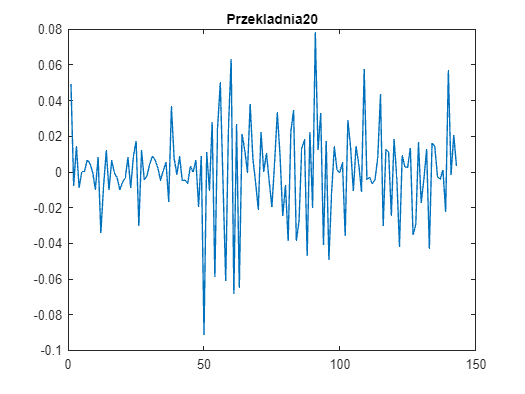

falka = 'dmey';
num = 10;

% P20
[c, l] = wavedec(P20, num, falka);
[d5_P20] = detcoef(c, l, num);
figure(1), plot(d5_P20), title('Przekladnia20');

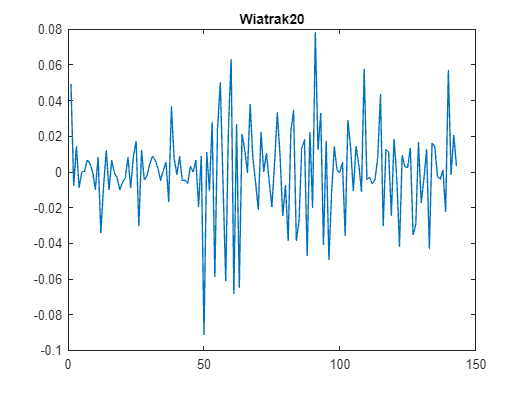

% P21
[c, l] = wavedec(P21, num, falka);
[d5_P21] = detcoef(c, l, num);
% P23
[c, l] = wavedec(P23, num, falka);
[d5_P23] = detcoef(c, l, num);
% P24
[c, l] = wavedec(P24, num, falka);
[d5_P24] = detcoef(c, l, num);
% W20
[c, l] = wavedec(P20, num, falka);
[d5_W20] = detcoef(c, l, num);
figure(5), plot(d5_W20), title('Wiatrak20');

% W21
[c, l] = wavedec(P21, num, falka);
[d5_W21] = detcoef(c, l, num);
% W23
[c, l] = wavedec(P23, num, falka);
[d5_W23] = detcoef(c, l, num);
% W24
[c, l] = wavedec(P24, num, falka);
[d5_W24] = detcoef(c, l, num);

### Zadanie 6

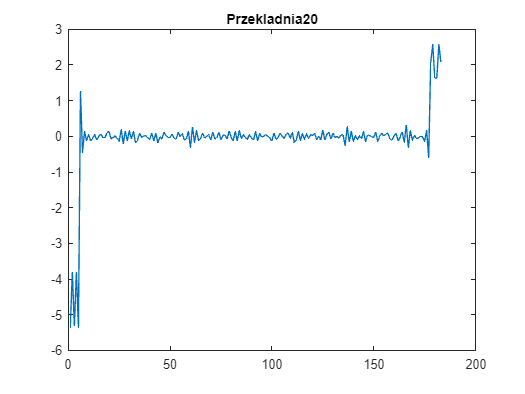

falka = 'bior3.5';
num = 8;

% P20
[c, l] = wavedec(P20, num, falka);
[d5_P20] = appcoef(c, l, falka, num);
figure(1), plot(d5_P20), title('Przekladnia20');

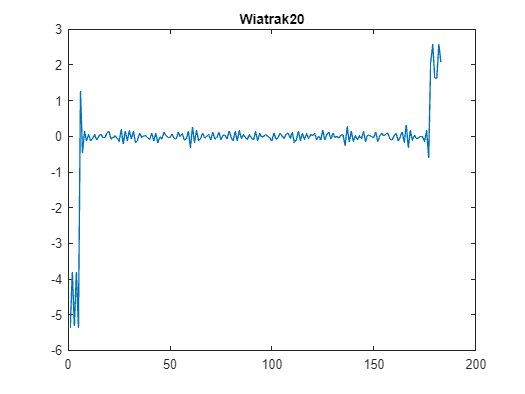

% P21
[c, l] = wavedec(P21, num, falka);
[d5_P21] = appcoef(c, l, falka, num);
% P23
[c, l] = wavedec(P23, num, falka);
[d5_P23] = appcoef(c, l, falka, num);
% P24
[c, l] = wavedec(P24, num, falka);
[d5_P24] = appcoef(c, l, falka, num);
% W20
[c, l] = wavedec(P20, num, falka);
[d5_W20] = appcoef(c, l, falka, num);
figure(5), plot(d5_W20), title('Wiatrak20');

% W21
[c, l] = wavedec(P21, num, falka);
[d5_W21] = appcoef(c, l, falka, num);
% W23
[c, l] = wavedec(P23, num, falka);
[d5_W23] = appcoef(c, l, falka, num);
% W24
[c, l] = wavedec(P24, num, falka);
[d5_W24] = appcoef(c, l, falka, num);

### Zadanie 7

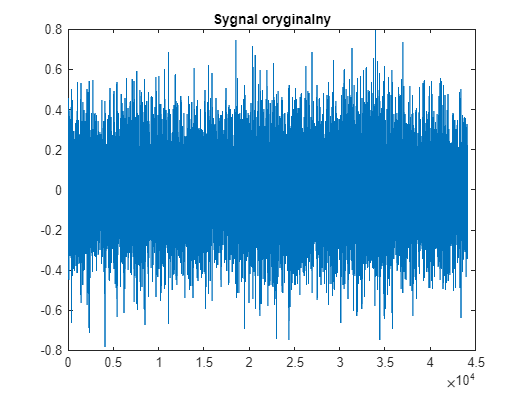

figure(1), plot(W20), title('Sygnal oryginalny'); 

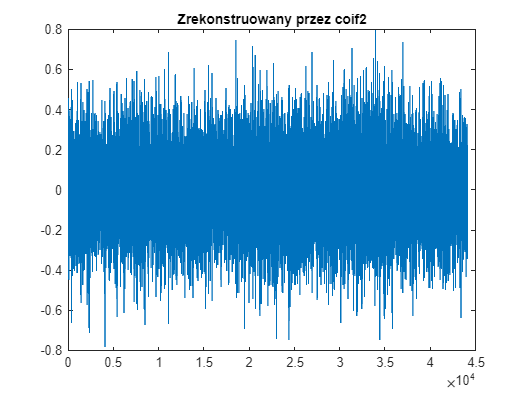

[c,l] = wavedec(W20,6, 'coif2'); 

Rec = waverec(c,l,'coif2'); 
figure(2), plot(Rec), title('Zrekonstruowany przez coif2');

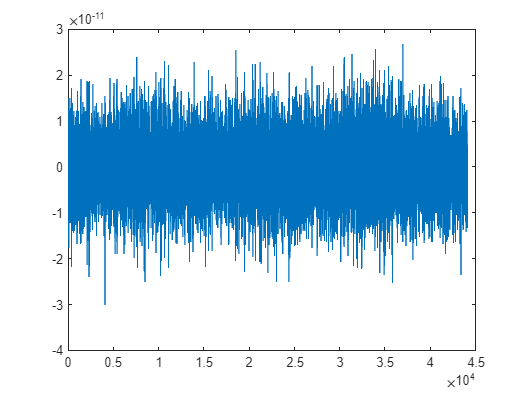

roznica = W20 - Rec;
figure(3), plot(roznica);

### Zadanie 8

figure(1), plot(W20), title('Sygnal oryginalny'); 

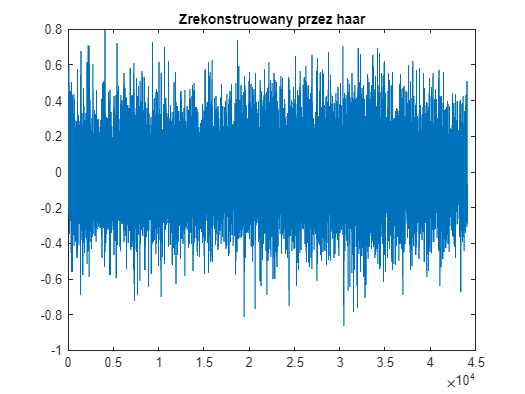

[c,l] = wavedec(W20,6, 'coif2'); 

Rec = waverec(c,l,'haar'); 
figure(2), plot(Rec), title('Zrekonstruowany przez haar');

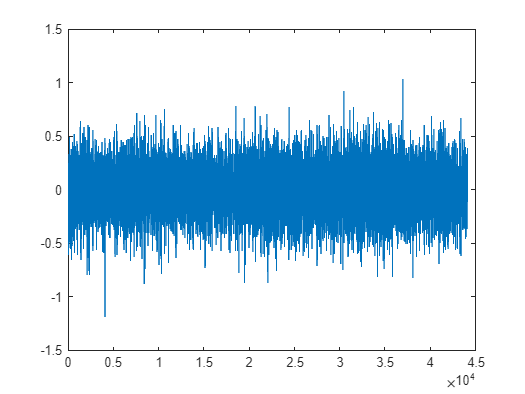

roznica = W20 - Rec;
figure(3), plot(roznica);

### Zadanie 9

falka = 'sym2';
num = 12;
% P20
[c, l] = wavedec(P20, num, falka);
[d5_P20] = appcoef(c, l, falka, num)

d5_P20 =    -6.0615
   -5.4489
   -0.0280
   -0.0563
   -0.0351
   -0.0220
    0.0180
   -0.0464
   -0.0022
    0.0116


% P21
[c, l] = wavedec(P21, num, falka);
[d5_P21] = appcoef(c, l, falka, num)

d5_P21 =   -10.4008
   -9.2888
   -0.0588
   -0.0549
    0.0850
   -0.0106
   -0.0371
   -0.0272
   -0.0633
   -0.0020


% P23
[c, l] = wavedec(P23, num, falka);
[d5_P23] = appcoef(c, l, falka, num)

d5_P23 =    10.5749
    9.4315
   -0.0491
    0.0030
    0.0188
    0.0083
    0.0023
   -0.0364
   -0.0107
   -0.0195


% P24
[c, l] = wavedec(P24, num, falka);
[d5_P24] = appcoef(c, l, falka, num)

d5_P24 =    -2.9775
   -2.6853
    0.0101
    0.0134
    0.0200
    0.0414
    0.0212
   -0.0261
   -0.0198
   -0.0244


% W20
[c, l] = wavedec(P20, num, falka);
[d5_W20] = appcoef(c, l, falka, num)

d5_W20 =    -6.0615
   -5.4489
   -0.0280
   -0.0563
   -0.0351
   -0.0220
    0.0180
   -0.0464
   -0.0022
    0.0116


% W21
[c, l] = wavedec(P21, num, falka);
[d5_W21] = appcoef(c, l, falka, num)

d5_W21 =   -10.4008
   -9.2888
   -0.0588
   -0.0549
    0.0850
   -0.0106
   -0.0371
   -0.0272
   -0.0633
   -0.0020


% W23
[c, l] = wavedec(P23, num, falka);
[d5_W23] = appcoef(c, l, falka, num)

d5_W23 =    10.5749
    9.4315
   -0.0491
    0.0030
    0.0188
    0.0083
    0.0023
   -0.0364
   -0.0107
   -0.0195


% W24
[c, l] = wavedec(P24, num, falka);
[d5_W24] = appcoef(c, l, falka, num)

d5_W24 =    -2.9775
   -2.6853
    0.0101
    0.0134
    0.0200
    0.0414
    0.0212
   -0.0261
   -0.0198
   -0.0244


### Zadanie 10

falka = 'sym2';
num = 12;
% P20
[c, l] = wavedec(P20, num, falka);
[d5_P20] = detcoef(c, l, num)

d5_P20 =    -0.2829
    1.3502
    0.0033
   -0.0617
   -0.0143
   -0.0035
    0.0055
    0.0433
   -0.0019
   -0.0346


% P21
[c, l] = wavedec(P21, num, falka);
[d5_P21] = detcoef(c, l, num)

d5_P21 =    -0.4967
    2.5062
    0.0001
   -0.0533
    0.0399
   -0.0138
    0.0137
    0.0289
   -0.0295
   -0.0063


% P23
[c, l] = wavedec(P23, num, falka);
[d5_P23] = detcoef(c, l, num)

d5_P23 =     0.4978
   -2.6198
    0.0496
   -0.0595
    0.0168
    0.0487
   -0.0051
    0.0044
    0.0325
    0.0574


% P24
[c, l] = wavedec(P24, num, falka);
[d5_P24] = detcoef(c, l, num)

d5_P24 =    -0.1423
    0.6197
    0.0059
   -0.0146
    0.0474
    0.0419
   -0.0730
   -0.0190
   -0.1116
    0.0176


% W20
[c, l] = wavedec(P20, num, falka);
[d5_W20] = detcoef(c, l, num)

d5_W20 =    -0.2829
    1.3502
    0.0033
   -0.0617
   -0.0143
   -0.0035
    0.0055
    0.0433
   -0.0019
   -0.0346


% W21
[c, l] = wavedec(P21, num, falka);
[d5_W21] = detcoef(c, l, num)

d5_W21 =    -0.4967
    2.5062
    0.0001
   -0.0533
    0.0399
   -0.0138
    0.0137
    0.0289
   -0.0295
   -0.0063


% W23
[c, l] = wavedec(P23, num, falka);
[d5_W23] = detcoef(c, l, num)

d5_W23 =     0.4978
   -2.6198
    0.0496
   -0.0595
    0.0168
    0.0487
   -0.0051
    0.0044
    0.0325
    0.0574


% W24
[c, l] = wavedec(P24, num, falka);
[d5_W24] = detcoef(c, l, num)

d5_W24 =    -0.1423
    0.6197
    0.0059
   -0.0146
    0.0474
    0.0419
   -0.0730
   -0.0190
   -0.1116
    0.0176
